# Identifying roundworm lines

Instructions are in the task pane to the left. Complete and submit each task one at a time.

imwrite(wormsBW, "./images/wormA05BW.jpg")

This code sets up the activity. 

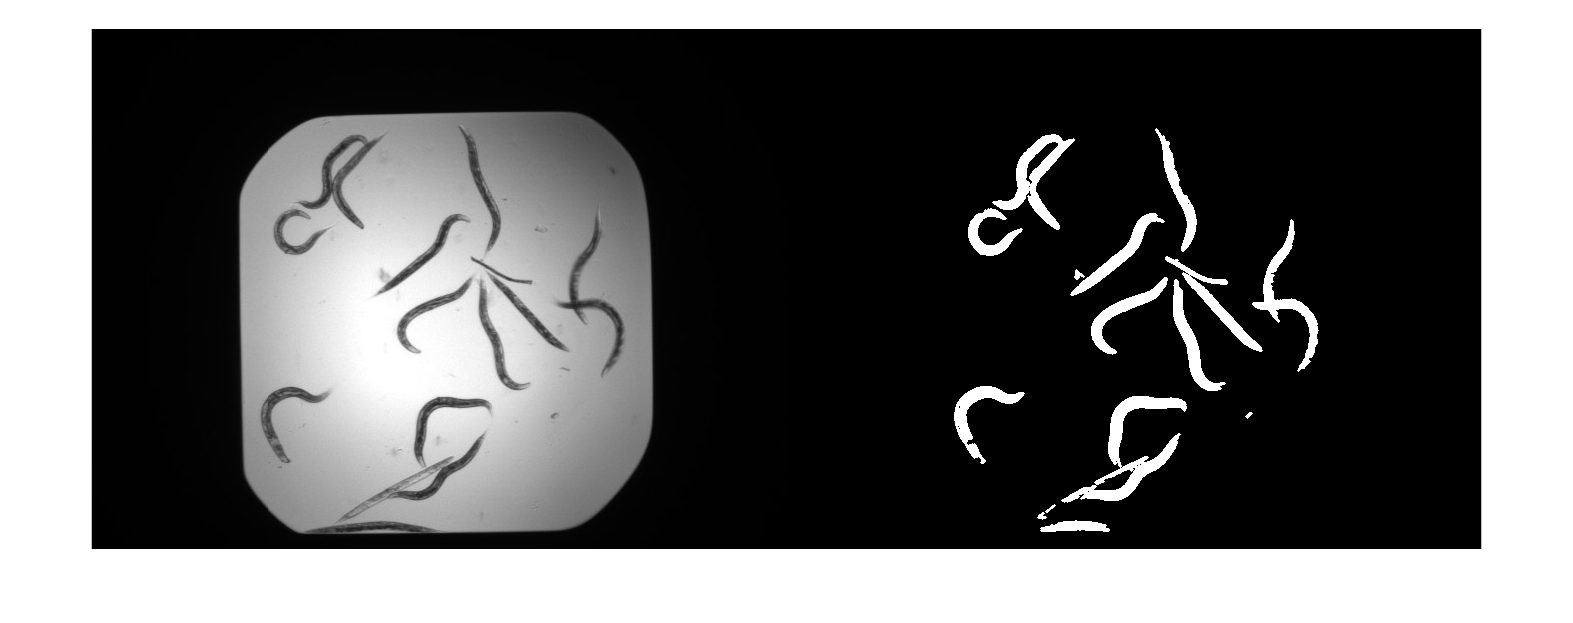

worms = imread("./images/wormA05.jpg");
wormsBW = createBinaryWorms(worms);
imshowpair(worms, wormsBW, "montage");

## Task 1

In this practice, you will detect straight lines in images of roundworms as a step toward detecting which slides contain live worms. The binarized image displayed on the right is stored in `wormsBW`.

To prevent extraneous lines from being detected, you'll want to skeletonize the image before detecting straight lines.

`skeleton` `=` `bwmorph``(``BW``,``method``,``n``)``;`

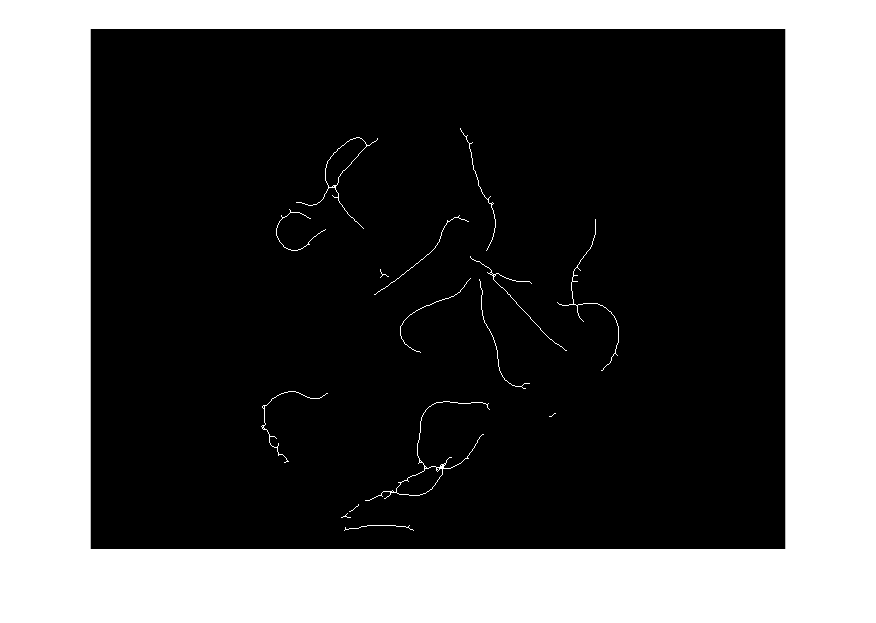

wormSkel = bwmorph(wormsBW, "skel", Inf);
imshow(wormSkel)

## Task 2

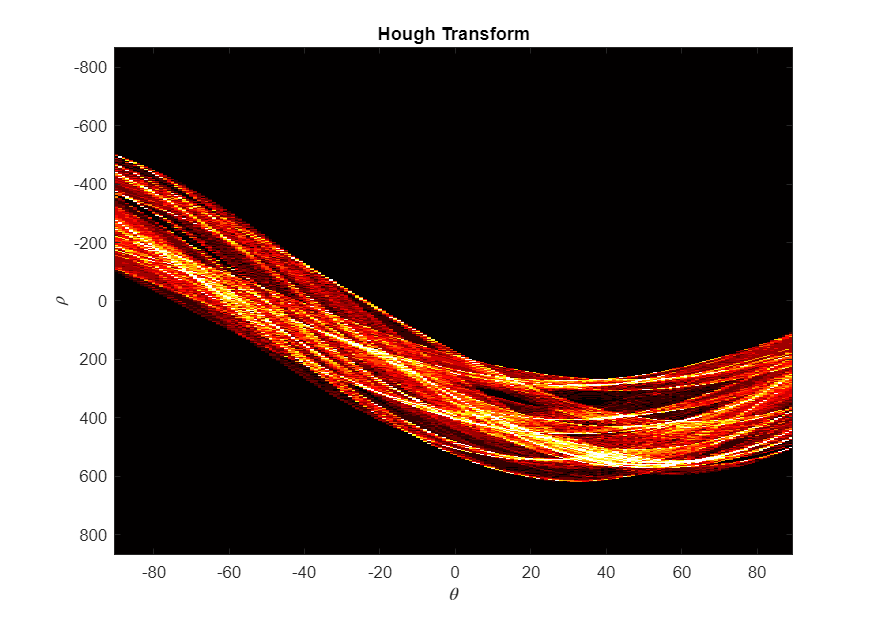

[H, T, R] = hough(wormSkel);
houghMatViz(H, T, R)

## Task 3 & 5

Did you notice that some overlapping lines were detected? That can happen when multiple peaks are found close to each other in the Hough transform. To alter this behavior, you can adjust the suppression neighborhood.

`peaks` `=` `houghpeaks``(``...,``"NHoodSize"``,``[``m` `n``])`

When a peak is located, `houghpeaks` will not find any other peaks within an m-b-n neighborhood. The default neighborhood size is approximately `size``(``H``)``/``50`. In this example, that evaluates to approximately `[``35` `4``]`. In order to avoid detecting overlapping lines, you can increase the size of the suppression neighborhood.

peaks = houghpeaks(H, 30, "NHoodSize", [55 11]);

## Task 4

With the peaks detected, you can complete the workflow by identifying the lines.

`lines` `=` `houghlines``(``BW``,``theta``,``rho``,``peaks``)`

lines = houghlines(wormSkel, T, R, peaks)

lines = 1×9 struct array with fields:
    point1
    point2
    theta
    rho


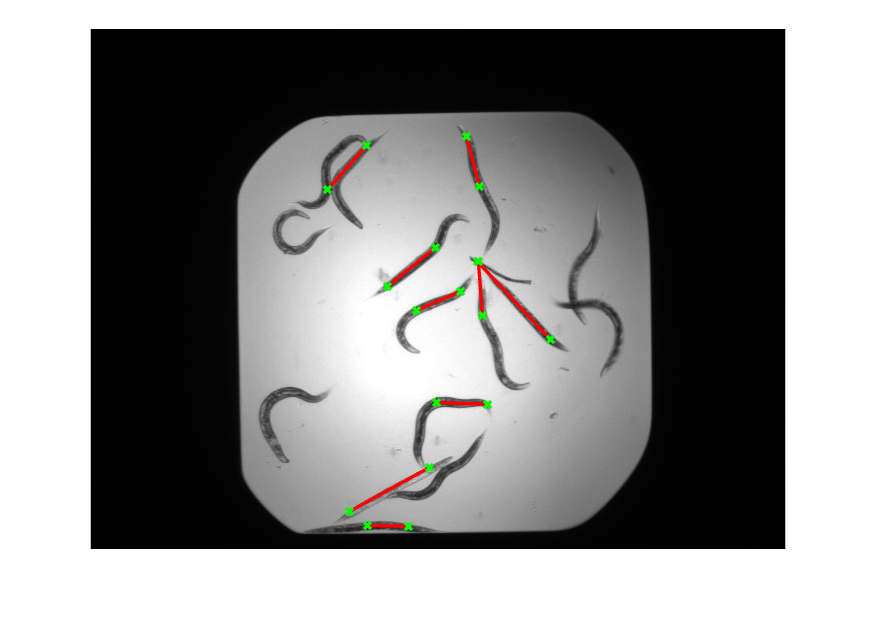

plotHoughLines(worms, lines);

function houghMatViz(H, T, R)
    % Convert the hough matrix to a grayscale image
    Hgray = mat2gray(H);
    % Enhance its brightness
    Hgray = imadjust(Hgray);
    % Display the hough transform
    imagesc(Hgray, "XData", T, "YData", R);    
    % Assign a colormap for the image
    colormap(hot);
    title("Hough Transform");
    % Add x-y labels
    xlabel("\theta")
    ylabel("\rho");
end

function plotHoughLines(image, lines)
    % Show the image
    imshow(image)
    % Plot the hough transform lines
    hold on    
    numLines = length(lines);
    for k = 1:numLines
        xy = [lines(k).point1; lines(k).point2];
        plot(xy(:, 1), xy(:, 2), "LineWidth", 2, "Color", "red",...
            "Marker", "x", "MarkerEdgeColor", "g");
    end
    hold off
end